
figure
plot(longaxis)
ylabel('diameter(pix)')
xlabel('frames (60 Hz)')
title('pupil diameter over time')

sizeLongAxis = size(longaxis,2)
sizeDf_bg = size(dfof_bg,3)

sizeOnsetFrame = size(onsetFrame) % indicies for frameT onsets
sizeDfV1 = size(dfofV1onsetChunks) % dfofV1onsetChunks is already
% made in early analysis, it's trials/onsets (rows) x 18 frames (columns)

% trying to line up pupil dimater trace with V1 dfof for each
% stim onset chunk

% I want to index long axis with the values in onsetFrame, 
% which are the indicies of imaging frames at the onset of a trial
% I need to index long axis w/ -3:onsetFrame+13 to get each "chunk"
% of pupil trace around each stim onset
% long axis is downsampled to 10Hz so time stamps are not needed,
% only imagaing frame indicies

% picking pre & post imaging frames
numPreStimFrames = 3;
numPostStimFrames = 14;

clear o
for o = 1:length(onsetImFrames)
    
    % then select only the imaging frames right before & after the onset imaging frame of each stim
    eachOnsetPupil = longaxis(1,onsetImFrames(o)-numPreStimFrames:onsetImFrames(o)+numPostStimFrames);
    
    allOnsetPupils(o,:) = eachOnsetPupil;

end

%sizeOfEachOnsetPupil = size(eachOnsetPupil)
sizeOfAllOnsetPupils = size(allOnsetPupils)

sizeOfAllOnsetPupils =         1872          18


% plot one trial
figure
plot(allOnsetPupils(400,:))


% get mean pupil diamter for each trial

clear p 

for p = 1:length(allOnsetPupils)
    
    meanPupilDiameterEachTrial = mean(allOnsetPupils(p,:));
    meanPupilDiameterAllTrials(1,p) = meanPupilDiameterEachTrial;
    
end

sizeMeanPupilDiameterAllTrials = size(meanPupilDiameterAllTrials)

sizeMeanPupilDiameterAllTrials =            1        1872


% noramlize pupil diamter to miniumum pupil diameter

meanPupilDiameterAllTrials = meanPupilDiameterAllTrials-min(meanPupilDiameterAllTrials);


figure
histogram(meanPupilDiameterAllTrials,'Normalization','probability')
title('frequency of pupil diameters')
xlabel('pupil diamater values')
ylabel('fraction of trials')


% indicies for trials that meet our threshold
% USE to INDEX PTSdfof onset CHUNKS

idxLargePupilTrials = find(meanPupilDiameterAllTrials>=12);
idxSmallPupilTrials = find(meanPupilDiameterAllTrials<=12);

numTrials = length(meanPupilDiameterAllTrials)

numTrials =         1872


numTrialsOverThresh = length(idxLargePupilTrials)

numTrialsOverThresh =    692


numTrialsUnderThresh = length(idxSmallPupilTrials)

numTrialsUnderThresh =         1085


percentTrialsOverThresh = (numTrialsOverThresh/numTrials)*100

percentTrialsOverThresh =        36.966


% make vector of stim conditions in order of presentation/trial,
% & list of unique stim params (for looping)
[conOrderedByTrialMeetCriteria,uniqueContrasts,durOrderedByTrialMeetCriteria,uniqueDurations,conAndDurOrderedByTrialMeetCriteria] = getStimParamsNtrialConds(stimDetails,trialCond,idxOnsetsMeetsCriteria);

% in preparation for making pixel wise figures of flurescene at different stim conditions,
% make figure legends
[reigons,cons4Legend,cons4axes,durs4Legend,durs4Axes] = getSubtitleLegendNaxesInfo(uniqueContrasts,uniqueDurations);

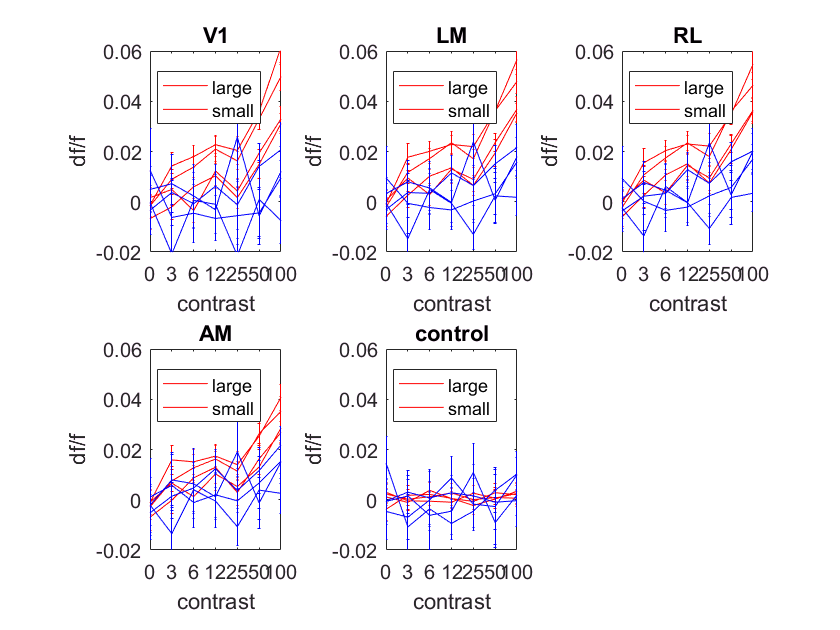

% small & large SAME PLOT

figure 
clear titleText
%titleText = sprintf(': CRF for STAT vs RUN'); % making char variables for sprintf/title later
%suptitle(sprintf('%s', date, subjName, titleText))
clear i
for i = 1:length(xPickedPts) % for each point
    
    clear meanBaselineFramesIthPtCthDthTrials
    clear dthCRF
    clear stdErr
    clear contStdErr

    clear d
    for d = 1:length(uniqueDurations) % at each duration
    
        clear cthDthMeanOverTrialsMeanOverFramesSq5FramesOverTrialsPTSdfof
        clear c
        for c = 1:length(uniqueContrasts) % for each duration at each contrast
            
             % for each POINT, for each DUR, get CRF at the dth dur

             clear cthDthTrials
             cthDthTrials = conAndDurOrderedByTrialMeetCriteria(1,:) == uniqueContrasts(c) & conAndDurOrderedByTrialMeetCriteria(2,:) == uniqueDurations(d);
             numTrials = sum(cthDthTrials);
             
             clear idxCthDthTrial
             idxCthDthTrial = find(cthDthTrials == 1);
             
             % clear idxCthDthRUNtrials
             % idxCthDthRUNtrials = intersect(idxCthDthTrial,idxRunTrials); % idxRunTrials was made in runSpeed2 script
             
             clear idxCthDthSTATtrials
             idxCthDthLARGEpupTrials = intersect(idxCthDthTrial,idxLargePupilTrials);
             
             % this is the same as the CRF process from earlier code
             % getting AVG DF/F over 3 FRAMES & dthCthTRIALS for each CONTRAST at this DURATION
             % returns # frames by # trials
             clear sq5FramesOverTrialsPTSdfof
             sq5FramesOverTrialsPTSdfof = squeeze(PTSdfof(i,peakFrameIdx,idxCthDthLARGEpupTrials));
            
             % take the mean over frames
             % returns 1 x # trials
             clear meanOverFramesSq5FramesOverTrialsPTSdfof
             meanOverFramesSq5FramesOverTrialsPTSdfof = mean(sq5FramesOverTrialsPTSdfof,1);
         
             % now take the mean over trials
             clear meanOverTrialsMeanOverFramesSq5FramesOverTrialsPTSdfof 
             meanOverTrialsMeanOverFramesSq5FramesOverTrialsPTSdfof = mean(meanOverFramesSq5FramesOverTrialsPTSdfof);
        
             % now I want to collect each c-th DRF value for this point
             % creates 1 x # contrasts for the d-th duration
             dthCRF(1,c) = meanOverTrialsMeanOverFramesSq5FramesOverTrialsPTSdfof; 
        
             % GET mean BASEline
             % the baseline for each CRF value is the mean of the baseline frames for
             % the ith point and cth contrast
             % get all frames & cth trials
             clear baselineFramesIthPtCthDthTrials
             baselineFramesIthPtCthDthTrials = squeeze((PTSdfof(i,baselineIdx,idxCthDthLARGEpupTrials)));
             % now have baseline frames x trials
             % take mean across trials 
             clear meanBaselineFramesIthPtCthDthTrials
             meanBaselineFramesIthPtCthDthTrials = mean(baselineFramesIthPtCthDthTrials,2);
             % take mean across frames
             meanBaselineFramesIthPtCthDthTrials = mean(meanBaselineFramesIthPtCthDthTrials,1);
            
             % do BASEline CORRECTION
             % subtract the cth baseline from the flourescence at each c
             dthCRF(c) = dthCRF(c)-meanBaselineFramesIthPtCthDthTrials; % clear this var in between subplots

            % STDERR
            % now I want to calulate the StdErr for each CRF point calulated above
            % (one err value for each contrast)
            % that means I want the error over trials, not over frames
            % that info is in the 'meanOverFramesSq5FramesOverTrialsPTSdfof' variable (1 x # trials)
            clear stdErr
            stdErr = std(meanOverFramesSq5FramesOverTrialsPTSdfof)/sqrt(length(idxCthDthLARGEpupTrials)); % length
            contStdErr(1,c) = stdErr; % clear outside j loop
             
        end % end c loop
     
        % once I've got that^ for the d-th duration, plot dth trace on ith subplot:
        subplot(2,3,i) 
        
        % 7 contrasts for x axis
        % x_axis = uniqueContrasts;
        x_axis = [1:length(uniqueContrasts)];
        errorbar(x_axis,dthCRF,contStdErr,'-r','MarkerSize',3) 
        title(reigons{i})
        
        %ylim([-0.025 0.01]) 
        %xlim([0, 8])
        ylim([-0.05 0.06]) 
        xlim([min(x_axis), max(x_axis)])
    
        ylabel('df/f')
        xlabel('contrast')

        %clear xt
        %xt={'0'; '3' ; '6' ; '12' ; '25' ; '50'; '100'} ; 
        %set(gca,'xtick',1:7); 
        %set(gca,'xticklabel',xt);
        
        
        hold on 
        
    end % end d loop

hold on
%legend(durs4Axes)
    
end % end i loop

hold on

% same but 

clear i
for i = 1:length(xPickedPts) % for each point
    
    clear meanBaselineFramesIthPtCthDthTrials
    clear dthCRF
    clear stdErr
    clear contStdErr

    clear d
    for d = 1:length(uniqueDurations) % at each duration
    
        clear cthDthMeanOverTrialsMeanOverFramesSq5FramesOverTrialsPTSdfof
        clear c
        for c = 1:length(uniqueContrasts) % for each duration at each contrast
            
             % for each POINT, for each DUR, get CRF at the dth dur

             clear cthDthTrials
             cthDthTrials = conAndDurOrderedByTrialMeetCriteria(1,:) == uniqueContrasts(c) & conAndDurOrderedByTrialMeetCriteria(2,:) == uniqueDurations(d);
             numTrials = sum(cthDthTrials);
             
             clear idxCthDthTrial
             idxCthDthTrial = find(cthDthTrials == 1);
             
             clear idxCthDthSMALLtrials
             idxCthDthSMALLpupTrials = intersect(idxCthDthTrial,idxSmallPupilTrials); % idxRunTrials was made in runSpeed2 script
             
             % clear idxCthDthSTATtrials
             % idxCthDthSTATtrials = idxStatTrials(intersect(idxCthDthTrial,idxStatTrials);
             
             % this is the same as the CRF process from earlier code
             % getting AVG DF/F over 3 FRAMES & dthCthTRIALS for each CONTRAST at this DURATION
             % returns # frames by # trials
             clear sq5FramesOverTrialsPTSdfof
             sq5FramesOverTrialsPTSdfof = squeeze(PTSdfof(i,peakFrameIdx,idxCthDthSMALLpupTrials));
            
             % take the mean over frames
             % returns 1 x # trials
             clear meanOverFramesSq5FramesOverTrialsPTSdfof
             meanOverFramesSq5FramesOverTrialsPTSdfof = mean(sq5FramesOverTrialsPTSdfof,1);
         
             % now take the mean over trials
             clear meanOverTrialsMeanOverFramesSq5FramesOverTrialsPTSdfof 
             meanOverTrialsMeanOverFramesSq5FramesOverTrialsPTSdfof = mean(meanOverFramesSq5FramesOverTrialsPTSdfof);
        
             % now I want to collect each c-th DRF value for this point
             % creates 1 x # contrasts for the d-th duration
             dthCRF(1,c) = meanOverTrialsMeanOverFramesSq5FramesOverTrialsPTSdfof; 
        
             % GET mean BASEline
             % the baseline for each CRF value is the mean of the baseline frames for
             % the ith point and cth contrast
             % get all frames & cth trials
             clear baselineFramesIthPtCthDthTrials
             baselineFramesIthPtCthDthTrials = squeeze((PTSdfof(i,baselineIdx,idxCthDthSMALLpupTrials)));
             % now have baseline frames x trials
             % take mean across trials 
             clear meanBaselineFramesIthPtCthDthTrials
             meanBaselineFramesIthPtCthDthTrials = mean(baselineFramesIthPtCthDthTrials,2);
             % take mean across frames
             meanBaselineFramesIthPtCthDthTrials = mean(meanBaselineFramesIthPtCthDthTrials,1);
            
             % do BASEline CORRECTION
             % subtract the cth baseline from the flourescence at each c
             dthCRF(c) = dthCRF(c)-meanBaselineFramesIthPtCthDthTrials; % clear this var in between subplots

            % STDERR
            % now I want to calulate the StdErr for each CRF point calulated above
            % (one err value for each contrast)
            % that means I want the error over trials, not over frames
            % that info is in the 'meanOverFramesSq5FramesOverTrialsPTSdfof' variable (1 x # trials)
            clear stdErr
            stdErr = std(meanOverFramesSq5FramesOverTrialsPTSdfof)/sqrt(length(idxCthDthSMALLpupTrials)); % length
            contStdErr(1,c) = stdErr; % clear outside j loop
             
        end % end c loop
     
        % once I've got that^ for the d-th duration, plot dth trace on ith subplot:
        subplot(2,3,i) 
        
        % 7 contrasts for x axis
        % x_axis = uniqueContrasts;
        x_axis = [1:length(uniqueContrasts)];
        errorbar(x_axis,dthCRF,contStdErr,'-b','MarkerSize',3) 
        title(reigons{i})
        
        ylim([-0.02 0.06]) 
        %xlim([0, 8])
        %ylim([-0.04 0.08]) 
        xlim([min(x_axis), max(x_axis)])
    
        ylabel('df/f')
        xlabel('contrast')

        clear xt
        xt={'0'; '3' ; '6' ; '12' ; '25' ; '50'; '100'} ; 
        set(gca,'xtick',1:7); 
        set(gca,'xticklabel',xt);
        
        hold on 
        
    end % end d loop

hold on
legend('large','small')
    
end % end i loop

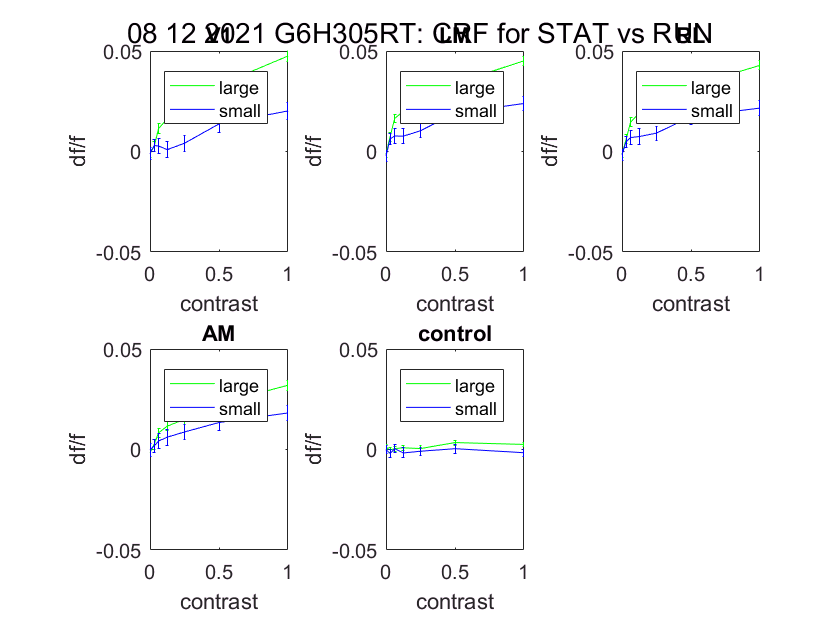

% STAT & RUN SAME PLOT

figure 
clear titleText
titleText = sprintf(': CRF for STAT vs RUN'); % making char variables for sprintf/title later
suptitle(sprintf('%s', date, subjName, titleText));

clear i
for i = 1:length(xPickedPts) % for each point
    
    clear meanBaselineFramesIthPtCthDthTrials
    clear dthCRF
    clear stdErr
    clear contStdErr

    clear d
    for d = 1:length(uniqueDurations) % at each duration
    
        clear cthDthMeanOverTrialsMeanOverFramesSq5FramesOverTrialsPTSdfof
        clear c
        for c = 1:length(uniqueContrasts) % for each duration at each contrast
            
             % for each POINT, for each DUR, get CRF at the dth dur

             clear cthDthTrials
             cthDthTrials = conAndDurOrderedByTrialMeetCriteria(1,:) == uniqueContrasts(c) & conAndDurOrderedByTrialMeetCriteria(2,:) == uniqueDurations(d);
             numTrials = sum(cthDthTrials);
             
             clear idxCthDthTrial
             idxCthDthTrial = find(cthDthTrials == 1);
             
             % clear idxCthDthRUNtrials
             % idxCthDthRUNtrials = intersect(idxCthDthTrial,idxRunTrials); % idxRunTrials was made in runSpeed2 script
             
             clear idxCthDthSTATtrials
             idxCthDthLARGEpupTrials = intersect(idxCthDthTrial,idxLargePupilTrials);
             
             % this is the same as the CRF process from earlier code
             % getting AVG DF/F over 3 FRAMES & dthCthTRIALS for each CONTRAST at this DURATION
             % returns # frames by # trials
             clear sq5FramesOverTrialsPTSdfof
             sq5FramesOverTrialsPTSdfof = squeeze(PTSdfof(i,peakFrameIdx,idxCthDthLARGEpupTrials));
            
             % take the mean over frames
             % returns 1 x # trials
             clear meanOverFramesSq5FramesOverTrialsPTSdfof
             meanOverFramesSq5FramesOverTrialsPTSdfof = mean(sq5FramesOverTrialsPTSdfof,1);
         
             % now take the mean over trials
             clear meanOverTrialsMeanOverFramesSq5FramesOverTrialsPTSdfof 
             meanOverTrialsMeanOverFramesSq5FramesOverTrialsPTSdfof = mean(meanOverFramesSq5FramesOverTrialsPTSdfof);
        
             % now I want to collect each c-th DRF value for this point
             % creates 1 x # contrasts for the d-th duration
             dthCRF(1,c) = meanOverTrialsMeanOverFramesSq5FramesOverTrialsPTSdfof; 
        
             % GET mean BASEline
             % the baseline for each CRF value is the mean of the baseline frames for
             % the ith point and cth contrast
             % get all frames & cth trials
             clear baselineFramesIthPtCthDthTrials
             baselineFramesIthPtCthDthTrials = squeeze((PTSdfof(i,baselineIdx,idxCthDthLARGEpupTrials)));
             % now have baseline frames x trials
             % take mean across trials 
             clear meanBaselineFramesIthPtCthDthTrials
             meanBaselineFramesIthPtCthDthTrials = mean(baselineFramesIthPtCthDthTrials,2);
             % take mean across frames
             meanBaselineFramesIthPtCthDthTrials = mean(meanBaselineFramesIthPtCthDthTrials,1);
            
             % do BASEline CORRECTION
             % subtract the cth baseline from the flourescence at each c
             dthCRF(c) = dthCRF(c)-meanBaselineFramesIthPtCthDthTrials; % clear this var in between subplots

            % STDERR
            % now I want to calulate the StdErr for each CRF point calulated above
            % (one err value for each contrast)
            % that means I want the error over trials, not over frames
            % that info is in the 'meanOverFramesSq5FramesOverTrialsPTSdfof' variable (1 x # trials)
            clear stdErr
            stdErr = std(meanOverFramesSq5FramesOverTrialsPTSdfof)/sqrt(length(idxCthDthLARGEpupTrials)); % length
            contStdErr(1,c) = stdErr; % clear outside j loop
             
        end % end c loop
     
        % once I've got that^ for the d-th duration, plot dth trace on ith subplot:
        subplot(2,3,i) 
        
        % 7 contrasts for x axis
        x_axis = uniqueContrasts;
        %x_axis = [1:length(uniqueContrasts)];
        errorbar(x_axis,dthCRF,contStdErr,'-g','MarkerSize',3) 
        title(reigons{i})
        
        %ylim([-0.025 0.01]) 
        %xlim([0, 8])
        %ylim([-0.04 0.08]) 
        xlim([min(x_axis), max(x_axis)])
    
        ylabel('df/f')
        xlabel('contrast')

        %clear xt
        %xt={'0'; '3' ; '6' ; '12' ; '25' ; '50'; '100'} ; 
        %set(gca,'xtick',1:7); 
        %set(gca,'xticklabel',xt);
        
        
        hold on 
        
    end % end d loop

hold on
%legend(durs4Axes)
    
end % end i loop

hold on

% same but LOG

clear i
for i = 1:length(xPickedPts) % for each point
    
    clear meanBaselineFramesIthPtCthDthTrials
    clear dthCRF
    clear stdErr
    clear contStdErr

    clear d
    for d = 1:length(uniqueDurations) % at each duration
    
        clear cthDthMeanOverTrialsMeanOverFramesSq5FramesOverTrialsPTSdfof
        clear c
        for c = 1:length(uniqueContrasts) % for each duration at each contrast
            
             % for each POINT, for each DUR, get CRF at the dth dur

             clear cthDthTrials
             cthDthTrials = conAndDurOrderedByTrialMeetCriteria(1,:) == uniqueContrasts(c) & conAndDurOrderedByTrialMeetCriteria(2,:) == uniqueDurations(d);
             numTrials = sum(cthDthTrials);
             
             clear idxCthDthTrial
             idxCthDthTrial = find(cthDthTrials == 1);
             
             clear idxCthDthRUNtrials
             idxCthDthSMALLpupTrials = intersect(idxCthDthTrial,idxSmallPupilTrials); % idxRunTrials was made in runSpeed2 script
             
             % clear idxCthDthSTATtrials
             % idxCthDthSTATtrials = idxStatTrials(intersect(idxCthDthTrial,idxStatTrials);
             
             % this is the same as the CRF process from earlier code
             % getting AVG DF/F over 3 FRAMES & dthCthTRIALS for each CONTRAST at this DURATION
             % returns # frames by # trials
             clear sq5FramesOverTrialsPTSdfof
             sq5FramesOverTrialsPTSdfof = squeeze(PTSdfof(i,peakFrameIdx,idxCthDthSMALLpupTrials));
            
             % take the mean over frames
             % returns 1 x # trials
             clear meanOverFramesSq5FramesOverTrialsPTSdfof
             meanOverFramesSq5FramesOverTrialsPTSdfof = mean(sq5FramesOverTrialsPTSdfof,1);
         
             % now take the mean over trials
             clear meanOverTrialsMeanOverFramesSq5FramesOverTrialsPTSdfof 
             meanOverTrialsMeanOverFramesSq5FramesOverTrialsPTSdfof = mean(meanOverFramesSq5FramesOverTrialsPTSdfof);
        
             % now I want to collect each c-th DRF value for this point
             % creates 1 x # contrasts for the d-th duration
             dthCRF(1,c) = meanOverTrialsMeanOverFramesSq5FramesOverTrialsPTSdfof; 
        
             % GET mean BASEline
             % the baseline for each CRF value is the mean of the baseline frames for
             % the ith point and cth contrast
             % get all frames & cth trials
             clear baselineFramesIthPtCthDthTrials
             baselineFramesIthPtCthDthTrials = squeeze((PTSdfof(i,baselineIdx,idxCthDthSMALLpupTrials)));
             % now have baseline frames x trials
             % take mean across trials 
             clear meanBaselineFramesIthPtCthDthTrials
             meanBaselineFramesIthPtCthDthTrials = mean(baselineFramesIthPtCthDthTrials,2);
             % take mean across frames
             meanBaselineFramesIthPtCthDthTrials = mean(meanBaselineFramesIthPtCthDthTrials,1);
            
             % do BASEline CORRECTION
             % subtract the cth baseline from the flourescence at each c
             dthCRF(c) = dthCRF(c)-meanBaselineFramesIthPtCthDthTrials; % clear this var in between subplots

            % STDERR
            % now I want to calulate the StdErr for each CRF point calulated above
            % (one err value for each contrast)
            % that means I want the error over trials, not over frames
            % that info is in the 'meanOverFramesSq5FramesOverTrialsPTSdfof' variable (1 x # trials)
            clear stdErr
            stdErr = std(meanOverFramesSq5FramesOverTrialsPTSdfof)/sqrt(length(idxCthDthSMALLpupTrials)); % length
            contStdErr(1,c) = stdErr; % clear outside j loop
             
        end % end c loop
     
        % once I've got that^ for the d-th duration, plot dth trace on ith subplot:
        subplot(2,3,i) 
        
        % 7 contrasts for x axis
        x_axis = uniqueContrasts;
        % x_axis = [1:length(uniqueContrasts)];
        errorbar(x_axis,dthCRF,contStdErr,'-b','MarkerSize',3) 
        title(reigons{i})
        
        ylim([-0.1 0.15]) 
        %xlim([0, 8])
        ylim([-0.05 0.05]) 
        xlim([min(x_axis), max(x_axis)])
    
        ylabel('df/f')
        xlabel('contrast')

%         clear xt
%         xt={'0'; '3' ; '6' ; '12' ; '25' ; '50'; '100'} ; 
%         set(gca,'xtick',1:7); 
%         set(gca,'xticklabel',xt);
        
        hold on 
        
    end % end d loop

hold on
legend('large','small')
    
end % end i loop

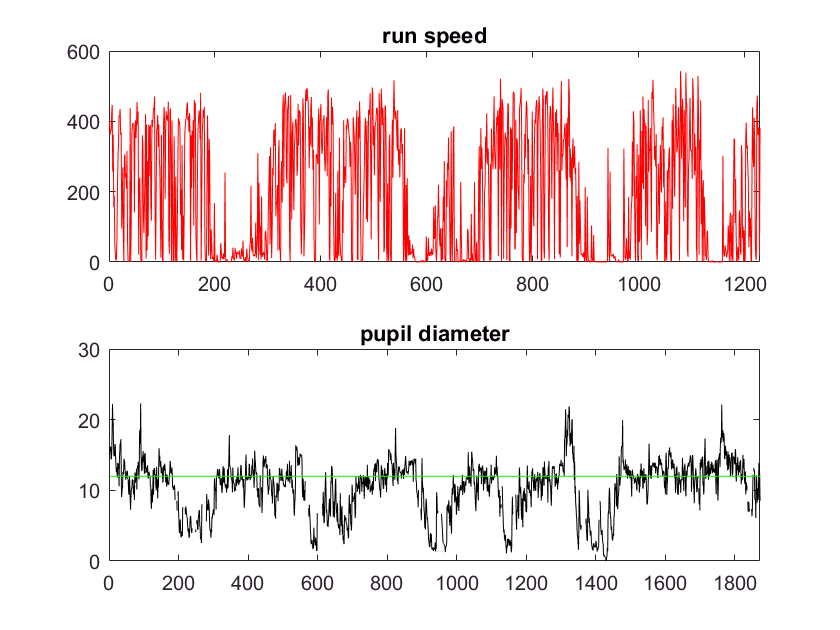

%meanPupilDiameterAllTrials needs to have the first & last 

x_axis = 1:length(meanSpeedAllTrials(1,1:1229));

%testmeanSpeedAllTrials = meanSpeedAllTrials(1,numPreStimFrames+1:length(meanSpeedAllTrials)-numPostStimFrames)
figure
subplot(2,1,1)
plot(x_axis,meanSpeedAllTrials(1,1:1229),'r')
title('run speed')
xlim([0 length(x_axis)])

x_axis = 1:length(meanPupilDiameterAllTrials);

subplot(2,1,2)
plot(x_axis,meanPupilDiameterAllTrials,'k')
hold on 

% thresh line
clear y
y(1,1:length(meanPupilDiameterAllTrials)) = threshold;

plot(1:length(y),y,'g')
title('pupil diameter')
xlim([0 length(meanPupilDiameterAllTrials)])

% above but smaller time range

aFewTrialsMeanSpeedAllTrials = meanSpeedAllTrials(1,900:1000)

aFewTrialsMeanSpeedAllTrials =    22.5164    1.2803    0.4227  185.6012   35.0348    0.8267    5.9743    0.4102    0.3552    0.2806    0.5071  103.8963    9.9853    5.9834    0.7163   76.5438    2.8741    0.8493    0.5006    0.5634    0.5528    0.8615    0.7647    0.6057    0.5022    0.3732    0.3852    0.4049    0.4475    0.3604    0.4391    0.2974    0.3292    0.3366    0.6080    0.3097    0.3382    0.5533    0.3623    0.3880    0.2758    0.2992  325.0169   89.9666   21.2075    3.3552  257.0150   34.7763   17.1559   16.7336


aFewTrialsMeanPupilDiameterAllTrials = meanPupilDiameterAllTrials(1,900:1000)

aFewTrialsMeanPupilDiameterAllTrials =    14.5501   11.7305   10.5387    9.6643   10.3193    8.5357    7.1569    6.8678    4.6870    5.1558    4.4641    7.6799    8.8331    8.1036    6.7664    5.9330    6.1405    5.1381    4.1928    3.0780    2.7916    2.1747    1.9619    2.1365    3.9371    2.6690    2.8192    3.8362    1.9090    1.6335    1.6855    1.9078    1.7397    1.4271    1.7522    1.9044    1.6505    1.7048    2.6393    1.3518    2.5535    1.6792    9.7237    9.0037    7.1373    6.7249    7.0865       NaN       NaN       NaN


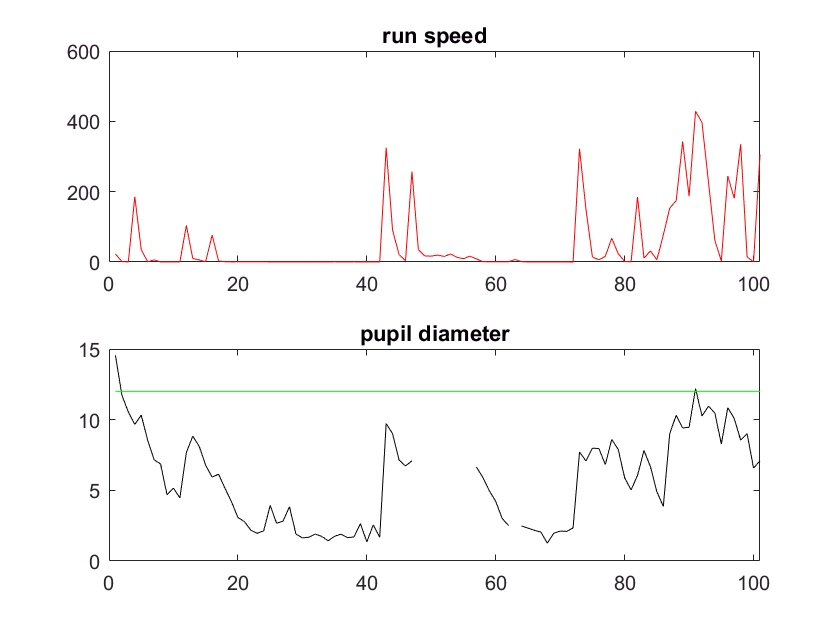


x_axis = 1:length(aFewTrialsMeanSpeedAllTrials);

figure
subplot(2,1,1)
plot(x_axis,aFewTrialsMeanSpeedAllTrials,'r')
title('run speed')
xlim([0 length(aFewTrialsMeanSpeedAllTrials)])

subplot(2,1,2)
plot(x_axis,aFewTrialsMeanPupilDiameterAllTrials,'k')
hold on 
subplot(2,1,2)
clear y
y(1,1:length(aFewTrialsMeanPupilDiameterAllTrials)) = 12;
plot(1:length(aFewTrialsMeanPupilDiameterAllTrials),y,'g')
title('pupil diameter')
xlim([0 length(aFewTrialsMeanSpeedAllTrials)])

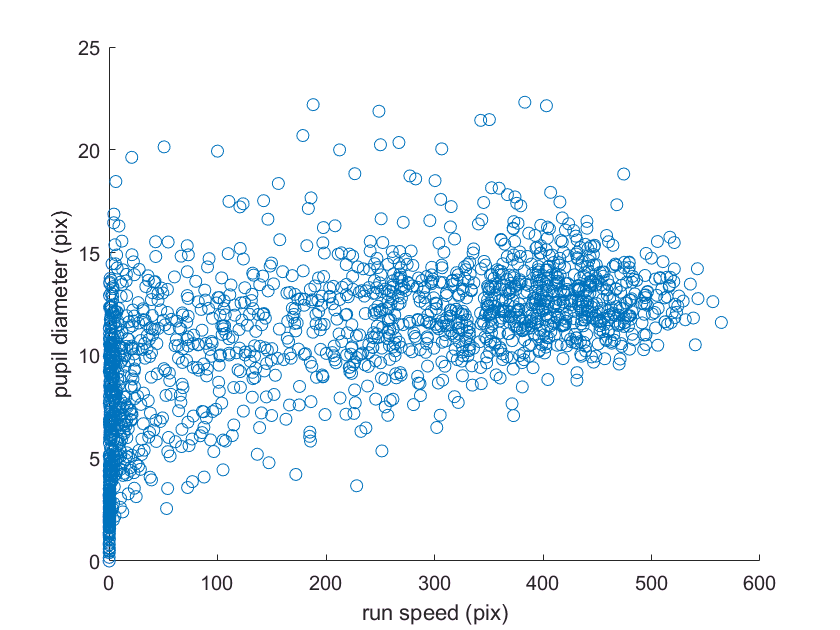

% SCATTER RUN VS PUP

figure
scatter(meanSpeedAllTrials,meanPupilDiameterAllTrials)
xlabel('run speed (pix)')
ylabel('pupil diameter (pix)')